Example

% num_bits=20000;
% samples_per_bit = 6; %number 0f samples per bit
% bit_rate = 200; % number of bits per second;
% delta_t=1/(samples_per_bit*bit_rate);
% Eb_over_No_in_dB = 6;
% Eb_over_No = 10^(Eb_over_No_in_dB/10);
% A=5;
% noisevar=(A^2*samples_per_bit)/(2*Eb_over_No);
% RNG=rand(1,num_bits); %generates a vector of length num_bits of numbers
% % uniformly distributes between 0 and 1.
% bits=floor(RNG+0.5); %RNG+0.5 is a vector of numbers uniformly distributed
% % between 0.5 and 1.5. Floor rounds down, so 50 percent should be 1 and 50
% % percent 0.
% for i=1:num_bits*samples_per_bit
%     x(i)=(2*bits(floor((i-1)/samples_per_bit)+1)-1)*A; %generates antipodal
% %     binary signal using square pulses of amplitude A
%     t(i)=i/(samples_per_bit*bit_rate); %creates time axis
% end
% noise=sqrt(noisevar)*randn(1,length(x));
% r=x+noise;
% %plot(t,x,t,r)
% %axis([0 t(samples_per_bit*num_bits) -A-5 A+5])
% for zz=1:num_bits*samples_per_bit
%     if mod(zz,samples_per_bit)==1
%         y(zz)=r(zz)/samples_per_bit;
%     else
%         y(zz)=(r(zz)/samples_per_bit +y(zz-1));
%     end
% end
% for zzz=1:num_bits
%     yT(zzz)=y(samples_per_bit*zzz);
%     if yT(zzz)>0
%         bhat(zzz)=1;
%     else
%         bhat(zzz)=0;
%     end
% end
% errors=bits-bhat; % when an element in bits and bhat are the same, the
% % corresponding element in errors is 0 otherwise it is 1 or -1.
% num_of_errors=sum(abs(errors));
% P_E=num_of_errors/num_bits
% expected_error_prob=0.5*erfc(sqrt(Eb_over_No))
% 
% 
% 


Question One

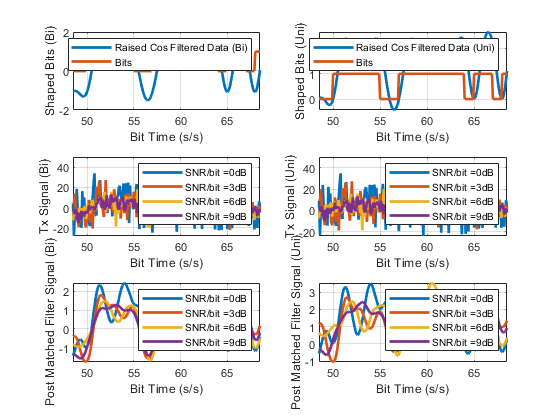

% Signal Params
% Data Params
numberOfBits = 256;
bits = randi([0, 1],[1, numberOfBits]);
bitRate = 10e6;
A = 5;
snrPerBit = [0, 3, 6, 9];
snrPerBit = 10.^(snrPerBit/10);

% Sampling Params
samplesPerBit = 10;
Fs = bitRate*samplesPerBit;
Ts = 1/Fs;
L = samplesPerBit*numberOfBits;
time = Ts*(0:L-1);
bitTime = 1/bitRate;


% Raised Cos Pulse Shape
rollOffFactor = 0.5;
p = @(t, dataRate, rollOff) ...
    cos(pi*dataRate*rollOff*t)...
    .*sinc(dataRate*t)...
    ./(1 - 4*rollOff^2*dataRate^2*t.^2) * dataRate;
% Rect Pulse Shape
rect = @(t, T) ...
    (heaviside(t) - heaviside(t - T*ones(size(t))));


% Generate Upsampled Bits
zoh = ones([1 samplesPerBit]);
bitsUpsampled = upsample(bits, samplesPerBit);
bitsZoh = convfft(bitsUpsampled, zoh);
bitsZoh = bitsZoh(1:L)';
bitsZoh(bitsZoh > 0.5) = 1;
bitsZoh(bitsZoh <= 0.5) = 0;

% Create Bipolar and Unipolar Data with Pulse Shaping
xBi = 2*A*bitsZoh - A;
xUni = A*bitsZoh;

xBiShaped = zeros(size(time));
xUniShaped = zeros(size(time));
for k = 1:numberOfBits
        xBiShaped = xBiShaped + A*(2*bits(k) - 1)*p(time - k*bitTime*ones(size(time)), bitRate, rollOffFactor);
        if bits(k) == 1
            xUniShaped = xUniShaped + A*p(time - k*bitTime*ones(size(time)), bitRate, rollOffFactor);
        end
end


xBiShaped = xBiShaped/sqrt(var(xBiShaped))*sqrt(var(xBi));
xUniShaped = xUniShaped/sqrt(var(xUniShaped))*sqrt(var(xUni));

% Check PSD of Data
[Sb, f1] = periodogram(bitsZoh,rectwin(length(bitsZoh)),length(bitsZoh), Fs, 'onesided');
[Sxb, f2] = periodogram(xBiShaped,rectwin(length(xBiShaped)),length(xBiShaped), Fs, 'onesided');
[Sxu, f3] = periodogram(xUniShaped,rectwin(length(xUniShaped)),length(xUniShaped), Fs, 'onesided');

% semilogx(f1, 10*log10(Sb))
% hold on
% semilogx(f2, 10*log10(Sxb), 'r')
% semilogx(f3, 10*log10(Sxu), 'c')
% grid on
% legend('Zero Order Hold', 'Raised Cos Filtered Bi', 'Raised Cos Filtered Uni')
% ylim([-130, -20])

% Generate Matched Filter Impulse Response
% Filter is matched to Raised Cos Pulse Shape
g = @(t, dataRate, rollOff) ...
    cos(pi*dataRate*rollOff*t).*sinc(dataRate*t)...
    ./(1 - 4*rollOff^2*dataRate^2*t.^2);
h = g(bitTime*ones(size(time)) - time, bitRate, rollOffFactor);

% Clean up filter impulse response
h(isinf(h)) = NaN;
h = fillmissing(h, 'linear');

% Loop over different Noise Powers
legendText = {};
bitErrorRateBi = zeros([1, length(snrPerBit)]);
bitErrorRateUni = zeros([1, length(snrPerBit)]);
for n = 1:length(snrPerBit)
    % Generate Noise 
    variance = (A^2*samplesPerBit)/(2*snrPerBit(n));
    noise = sqrt(variance)*randn(size(time));
    
    % Create Rx Sequence
    rxSequenceBi = xBiShaped + noise;
    rxSequenceUni = xUniShaped + noise/sqrt(2);
    
    % Apply Matched Filter to Rx Sequence
    yBi = convfft(rxSequenceBi, h);
    yUni = convfft(rxSequenceUni, h);
    
    % Shift Filtered Vectors to corect for length mismatch
    % Normalize to unit variance
    [RyBi, tau3] = xcorr(yBi, rxSequenceBi);
    [RyUni, tau4] = xcorr(yUni, rxSequenceUni);
    
    idx3 = find(RyBi == max(RyBi));
    idx3 = tau3(idx3);
    idx3 = abs(idx3);
    
    idx4 = find(RyUni == max(RyUni));
    idx4 = tau4(idx4);
    idx4 = abs(idx4);
    
    yBi = yBi(idx3:(L+idx3-1))';
    yBi = yBi/sqrt(var(yBi));
    
    yUni = yUni(idx4:(L+idx4-1))';
    yUni = yUni/sqrt(var(yUni));
    
    % Decimate Rx Signal to contain 1 sample per bit
    mUni = zeros([1, numberOfBits]);
    mBi = zeros([1, numberOfBits]);
    for k = 1:numberOfBits  
        for tau = (k-1)*samplesPerBit+1:k*samplesPerBit
            if mod(time(tau), bitTime) == 0
                mUni(k) = yUni(tau);
                mBi(k) = yBi(tau);
            end
        end
    end
    
    % Threshold Decimated Rx Signal to Recover Bits
    mBi = sign(mBi);
    mUni = sign(mUni - (max(mUni)+min(mUni))/2);
    
    % Check for Sample Delay
    [RbmBi, tau5] = xcorr(mBi, bits, 'biased');
    idx5 = find(RbmBi == max(RbmBi));
    idx5 = tau5(idx5);
    idx5 = abs(idx5);
    
    [RbmUni, tau6] = xcorr(mUni, bits, 'biased');
    idx6 = find(RbmUni == max(RbmUni));
    idx6 = tau6(idx6);
    idx6 = abs(idx6);
    % plot(tau, RbmBi)
    % grid on
    
    mBiShift = mBi(idx5+1:(length(mBi)+idx5-1));
    mBiShift = mBiShift/2 + 0.5;
    
    % Adjust for Sample Delay Caused by Matched Filter
    mUniShift = mUni(idx6+1:(length(mUni)+idx6-1));
    mUniShift = mUniShift/2 + 0.5;
    
    bitsShift = bits(1:end-1);
    
    % Check for 0 Shift between Bits and Rx Signal
    % [RbmBiShift, tauShift] = xcorr(mBiShift, bitsShift, 'biased');
    % plot(tauShift, RbmBiShift)
    % grid on
    
    % Calculate Bit Error Rate
    bitCheckBi = xor(bitsShift, mBiShift);
    bitErrorRateBi(n) = sum(bitCheckBi)/numberOfBits*100;
    
    bitCheckUni = xor(bitsShift, mUniShift);
    bitErrorRateUni(n) = sum(bitCheckUni)/numberOfBits*100;
    
    legendText{n} = strcat('SNR/bit = ', num2str(10*log10(snrPerBit(n))), 'dB');
    
    subplot(3,2,3)
    plot(time/bitTime, rxSequenceBi, 'LineWidth', 2)
    hold on
    
    subplot(3,2,4)
    plot(time/bitTime, rxSequenceUni, 'LineWidth', 2)
    hold on
    
    subplot(3,2,5)
    plot(time/bitTime, yBi, 'LineWidth', 2)
    hold on
    
    subplot(3,2,6)
    plot(time/bitTime, yUni, 'LineWidth', 2)
    hold on
end

subplot(3,2,1)
plot(time/bitTime, xBiShaped/sqrt(var(xBiShaped)), 'LineWidth', 2)
hold on
plot(time/bitTime, bitsZoh, 'LineWidth', 2)


subplot(3,2,2)
plot(time/bitTime, xUniShaped/sqrt(var(xUniShaped)), 'LineWidth', 2)
hold on
plot(time/bitTime, bitsZoh, 'LineWidth', 2)
grid on


plotPeriod = 20;
midlePlotPoint = randi([1+plotPeriod, round(max(time/bitTime))-plotPeriod], [1, 1]);

subplot(3,2,1)
xlim([midlePlotPoint/2-plotPeriod/2, midlePlotPoint/2+plotPeriod/2])
grid on
xlabel('Bit Time (s/s)')
ylabel('Shaped Bits (Bi)')
legend('Raised Cos Filtered Data (Bi)', 'Bits')

subplot(3,2,2)
xlim([midlePlotPoint/2-plotPeriod/2, midlePlotPoint/2+plotPeriod/2])
grid on
xlabel('Bit Time (s/s)')
ylabel('Shaped Bits (Uni)')
legend('Raised Cos Filtered Data (Uni)', 'Bits')

subplot(3,2,3)
xlim([midlePlotPoint/2-plotPeriod/2, midlePlotPoint/2+plotPeriod/2])
grid on
xlabel('Bit Time (s/s)')
ylabel('Tx Signal (Bi)')
legend(legendText)

subplot(3,2,4)
xlim([midlePlotPoint/2-plotPeriod/2, midlePlotPoint/2+plotPeriod/2])
grid on
xlabel('Bit Time (s/s)')
ylabel('Tx Signal (Uni)')
legend(legendText)

subplot(3,2,5)
xlim([midlePlotPoint/2-plotPeriod/2, midlePlotPoint/2+plotPeriod/2])
grid on
xlabel('Bit Time (s/s)')
ylabel('Post Matched Filter Signal (Bi)')
legend(legendText)

subplot(3,2,6)
xlim([midlePlotPoint/2-plotPeriod/2, midlePlotPoint/2+plotPeriod/2])
grid on
xlabel('Bit Time (s/s)')
ylabel('Post Matched Filter Signal (Uni)')
legend(legendText)

Question 2

% Signal Params
% Data Params
numberOfBits = 10^5;
bits = randi([0, 1],[1, numberOfBits]);
bitRate = 10e6;
A = 5;
% snrPerBit = [0, 3, 6, 9];
snrPerBit = linspace(0,30, 31);
snrPerBit = 10.^(snrPerBit/10);
% snrPerBit = 0;

% Sampling Params
samplesPerBit = 10;
Fs = bitRate*samplesPerBit;
Ts = 1/Fs;
L = samplesPerBit*numberOfBits;
time = Ts*(0:L-1);
bitTime = 1/bitRate;


% Raised Cos Pulse Shape
rollOffFactor = 0.5;
p = @(t, dataRate, rollOff) ...
    cos(pi*dataRate*rollOff*t)...
    .*sinc(dataRate*t)...
    ./(1 - 4*rollOff^2*dataRate^2*t.^2) * dataRate;
% Rect Pulse Shape
rect = @(t, T) ...
    (heaviside(t) - heaviside(t - T*ones(size(t))));


% Generate Upsampled Bits
zoh = ones([1 samplesPerBit]);
bitsUpsampled = upsample(bits, samplesPerBit);
bitsZoh = convfft(bitsUpsampled, zoh);
bitsZoh = bitsZoh(1:L)';
bitsZoh(bitsZoh > 0.5) = 1;
bitsZoh(bitsZoh <= 0.5) = 0;

% Create Bipolar and Unipolar Data with Pulse Shaping
xBi = 2*A*bitsZoh - A;
xUni = A*bitsZoh;

rcFilter = p(time - max(time)/2, bitRate, rollOffFactor);

xBiShaped = convfft(bitsUpsampled, rcFilter);
xUniShaped = convfft(bitsUpsampled, rcFilter);



% % Shift Shaped Vectors to corect for length mismatch (for RC Filtering)
[RxBi, tau1] = xcorr(bitsZoh, xBiShaped);
[RxUni, tau2] = xcorr(bitsZoh, xUniShaped);

idx1 = find(RxBi == max(RxBi));
idx1 = tau1(idx1);
idx1 = abs(idx1);

idx2 = find(RxUni == max(RxUni));
idx2 = tau1(idx2);
idx2 = abs(idx2);

xBiShaped = xBiShaped(idx1:(L+idx1-1))';
xBiShaped = xBiShaped - mean(xBiShaped);
xBiShaped = xBiShaped/sqrt(var(xBiShaped))*sqrt(var(xBi));

xUniShaped = xUniShaped(idx2:(L+idx2-1))';
xUniShaped = xUniShaped/sqrt(var(xUniShaped))*sqrt(var(xUni));




% xBiShaped = zeros(size(time));
% xUniShaped = zeros(size(time));
% for k = 1:numberOfBits
%         xBiShaped = xBiShaped + A*(2*bits(k) - 1)*p(time - k*bitTime*ones(size(time)), bitRate, rollOffFactor);
%         if bits(k) == 1
%             xUniShaped = xUniShaped + A*p(time - k*bitTime*ones(size(time)), bitRate, rollOffFactor);
%         end
% end
% xBiShaped = xBi;
% xUniShaped = xUni;
% xBiShaped = xBiShaped/sqrt(var(xBiShaped))*sqrt(var(xBi));
% xUniShaped = xUniShaped/sqrt(var(xUniShaped))*sqrt(var(xUni));


% Check PSD of Data
[Sb, f1] = periodogram(bitsZoh,rectwin(length(bitsZoh)),length(bitsZoh), Fs, 'onesided');
[Sxb, f2] = periodogram(xBiShaped,rectwin(length(xBiShaped)),length(xBiShaped), Fs, 'onesided');
[Sxu, f3] = periodogram(xUniShaped,rectwin(length(xUniShaped)),length(xUniShaped), Fs, 'onesided');

% semilogx(f1, 10*log10(Sb))
% hold on
% semilogx(f2, 10*log10(Sxb), 'r')
% semilogx(f3, 10*log10(Sxu), 'c')
% grid on
% legend('Zero Order Hold', 'Raised Cos Filtered Bi', 'Raised Cos Filtered Uni')
% % ylim([-130, -20])

% Generate Matched Filter Impulse Response
% Filter is matched to Raised Cos Pulse Shape
g = @(t, dataRate, rollOff) ...
    cos(pi*dataRate*rollOff*t).*sinc(dataRate*t)...
    ./(1 - 4*rollOff^2*dataRate^2*t.^2);
h = g(bitTime*ones(size(time)) - time, bitRate, rollOffFactor);
% h = zoh;

% Clean up filter impulse response
% h(isinf(h)) = NaN;
% h = fillmissing(h, 'linear');

% Loop over different Noise Powers
bitErrorRateBi = zeros([1, length(snrPerBit)]);
bitErrorRateUni = zeros([1, length(snrPerBit)]);
SNRbi = zeros([1, length(snrPerBit)]);
SNRuni = zeros([1, length(snrPerBit)]);
for n = 1:length(snrPerBit)
    % Generate Noise 
    variance = (A^2*samplesPerBit)/(2*snrPerBit(n));
    noise = sqrt(variance)*randn(size(time));
    
    SNRbi(n) = var(xBiShaped)/var(noise);
    SNRuni(n) = var(xUniShaped)/var(noise/sqrt(2));
    
    % Create Rx Sequence
    rxSequenceBi = xBiShaped + noise;
    rxSequenceUni = xUniShaped + noise/sqrt(2);
    
    % Apply Matched Filter to Rx Sequence
    yBi = convfft(rxSequenceBi, h);
    yUni = convfft(rxSequenceUni, h);
    
    % Shift Filtered Vectors to corect for length mismatch
    % Normalize to unit variance
    [RyBi, tau3] = xcorr(yBi, rxSequenceBi);
    [RyUni, tau4] = xcorr(yUni, rxSequenceUni);
    
    idx3 = find(RyBi == max(RyBi));
    idx3 = tau3(idx3);
    idx3 = abs(idx3);
    
    idx4 = find(RyUni == max(RyUni));
    idx4 = tau4(idx4);
    idx4 = abs(idx4);
    
    yBi = yBi(idx3:(L+idx3-1))';
    yBi = yBi/sqrt(var(yBi));
    
    yUni = yUni(idx4:(L+idx4-1))';
    yUni = yUni/sqrt(var(yUni));
    
    % Decimate Rx Signal to contain 1 sample per bit
    mUni = zeros([1, numberOfBits]);
    mBi = zeros([1, numberOfBits]);
    for k = 1:numberOfBits  
        for tau = (k-1)*samplesPerBit+1:k*samplesPerBit
            if mod(time(tau), bitTime) == 0
                mUni(k) = yUni(tau);
                mBi(k) = yBi(tau);
%                 disp(tau)
            end
        end
    end
    
    % Threshold Decimated Rx Signal to Recover Bits
    mBi = sign(mBi);
    mUni = sign(mUni - (max(mUni)+min(mUni))/2);
    
    % Check for Sample Delay
    [RbmBi, tau5] = xcorr(mBi, bits, 'biased');
    idx5 = find(RbmBi == max(RbmBi));
    idx5 = tau5(idx5);
    idx5 = abs(idx5);
    
    [RbmUni, tau6] = xcorr(mUni, bits, 'biased');
    idx6 = find(RbmUni == max(RbmUni));
    idx6 = tau6(idx6);
    idx6 = abs(idx6);
    % plot(tau, RbmBi)
    % grid on
    
    mBiShift = mBi(idx5+1:(length(mBi)+idx5-1));
    mBiShift = mBiShift/2 + 0.5;
    
    % Adjust for Sample Delay Caused by Matched Filter
    mUniShift = mUni(idx6+1:(length(mUni)+idx6-1));
    mUniShift = mUniShift/2 + 0.5;
    
    bitsShift = bits(1:end-1);
    
    % Check for 0 Shift between Bits and Rx Signal
    % [RbmBiShift, tauShift] = xcorr(mBiShift, bitsShift, 'biased');
    % plot(tauShift, RbmBiShift)
    % grid on
    
    % Calculate Bit Error Rate
    bitCheckBi = xor(bitsShift, mBiShift);
    bitErrorRateBi(n) = sum(bitCheckBi)/numberOfBits;
    
    bitCheckUni = xor(bitsShift, mUniShift);
    bitErrorRateUni(n) = sum(bitCheckUni)/numberOfBits;
    disp(strcat('Step:_  ', num2str(n), ' is done'))
end


x = linspace(0, 20, 1000);
x = 10.^(x/10);

berBi = 0.5*erfc(sqrt(2*x)/sqrt(2));
berUni = 0.5*erfc(sqrt(x)/sqrt(2));

semilogy(10*log10(SNRbi), bitErrorRateBi)
hold on
semilogy(10*log10(SNRuni), bitErrorRateUni)
semilogy(10*log10(x), berBi)
semilogy(10*log10(x), berUni)
xlabel('SNR/bit (dB)')
ylabel('Bit Error Rate')
grid on
legend('Bipolar Signal', 'Unipolar Signal', 'Theo Bipolar Signal', 'Theo Unipolar Signal')
ylim([1e-14, 1e0])
xlim([0 20])


